## **扩展卡尔曼滤波**

### 实例1

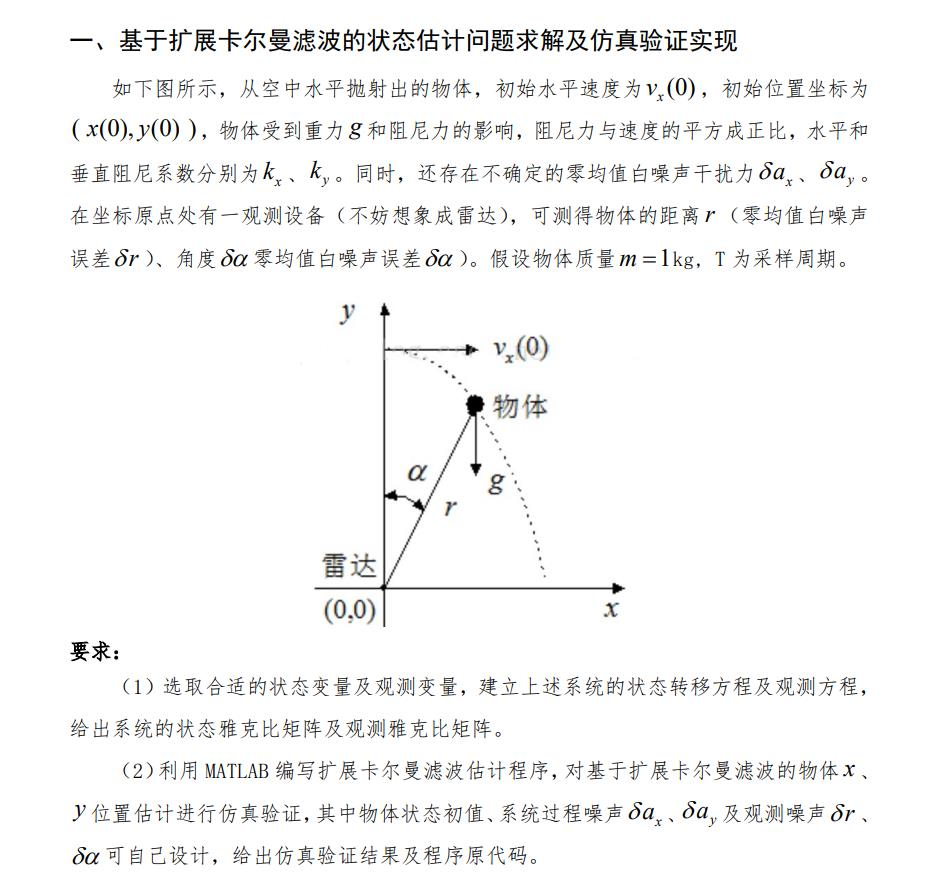

clear
clc

### 初始参数

状态函数：

[ x_k v_xk y_k v_yk]'

X = [0 10 200 0]';
t = 10;
T = 0.1;
m = 1;
kx = 0.01;
ky = 0.05;
g = -9.8;
Status = [T,g,m,kx,ky];
I = eye(4);

H = zeros(2,4);


% 初始的误差协方差矩阵
P_k1  = zeros(4,4);
% 噪声
Q = zeros(4,4);
Q(2,2) = 5;
Q(4,4) = 5;
R = eye(2);
R(1,1) = 0.0004;
R(2,2) = 3;
P_k1,Q,R

P_k1 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Q =      0     0     0     0
     0     5     0     0
     0     0     0     0
     0     0     0     5


R =     0.0004         0
         0    3.0000


X_real = X;
X_real1 = X;
X_head1 = X;
X_headp = zeros(4,1);
X_head = zeros(4,1);


XY = zeros(t/T,4);
ZZ = zeros(t/T,2);


生成 A H 矩阵

A = [1          T               0       0; 
     0   1-2*T/m*kx*X(2)        0       0; 
     0          0               1       T;
     0          0               0   1+2*T/m*ky*X(4)];
H = zeros(2,4);


迭代计算

rng(10);
for i = 1: t/T
    % 构造真实值
    X_real = CreatRealDatas(X_real1, Status, Q);
    % 构造观测值
    Zk = CreatObserveDatas(X_real, R);
    % 计算先验值
    X_headp = CalculatePriorValue(X_head1, Status);
    % 更新 A H 矩阵
    [A, H] = UpdateAHmatrix(X_head1, Status);
    % 误差协方差矩阵 Pk 的先验值
    Pkp = A*P_k1*A' + Q;
    % 计算 Kalman Gain
    Kk = Pkp*H'*(H*Pkp*H'+ R)^-1;
    % 计算 后验估计
    


!!!!! 这个地方

    ZZ_a = atan(X_headp(1)/X_headp(3));
    ZZ_r = sqrt(X_headp(1)^2 + X_headp(3)^2);
    abc = [ZZ_a,ZZ_r]';
    

    % X_head = X_headp + Kk*(Zk - H*X_headp);
    X_head = X_headp + Kk*(Zk - abc);
    % 更新误差的协方差矩阵
    Pk = (I - Kk*H)*Pkp;

数据更新

   
    X_real1 = X_real;
    X_head1 = X_head;
    P_k1 = Pk;
    
    XY(i,:) = X_real;
    Xh(i,:) = X_head;
    ZZ(i,:) = Zk;
end


绘制图像

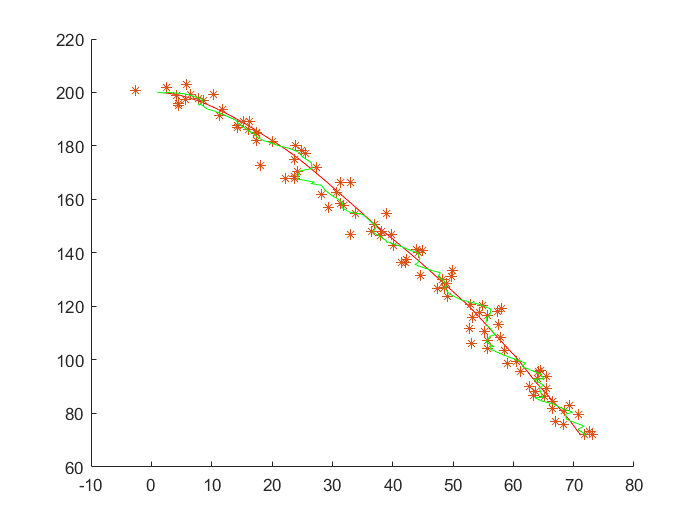

figure(1)
hold on
ZZ2 = [ZZ(:,2).*sin(ZZ(:,1)),ZZ(:,2).*cos(ZZ(:,1))];
plot(XY(:,1),XY(:,3),'r');
plot(ZZ2(:,1),ZZ2(:,2),'*');
plot(Xh(:,1),Xh(:,3),'g');

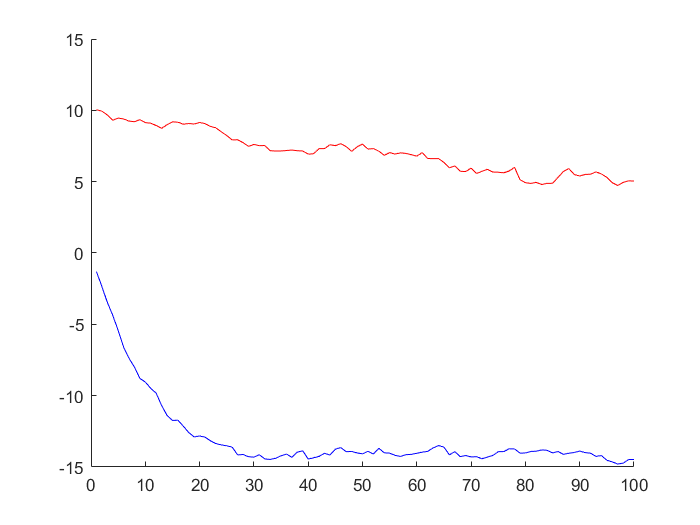


figure(2)
hold on
plot(XY(:,2),'r')
plot(XY(:,4),'b')

## 函数创建

- 构造真实值

function X_real = CreatRealDatas(X_real1, Status, Q)
    X_k1 = X_real1(1); V_xk1 = X_real1(2); Y_k1 = X_real1(3); V_yk1 = X_real1(4);
    T = Status(1); g = Status(2); m = Status(3); kx =Status(4); ky = Status(5);
    
    X_k = X_k1 + T*V_xk1;
    if V_xk1 >= 0
        V_xk = V_xk1 - T/m*kx * V_xk1*V_xk1 + Q(2,2)^0.5*randn(1)*T;
    else
        V_xk = V_xk1 + T/m*kx * V_xk1*V_xk1 + Q(2,2)^0.5*randn(1)*T;
    end
    
    Y_k = Y_k1 + T*V_yk1;
    if V_yk1 >= 0
        V_yk = V_yk1 + T*g - T/m*ky * V_yk1*V_yk1  + Q(4,4)^0.5*randn(1)*T;
    else
        V_yk = V_yk1 + T*g + T/m*ky * V_yk1*V_yk1  + Q(4,4)^0.5*randn(1)*T;
    end
    X_real = [X_k V_xk Y_k V_yk]';
end

2. 构造观测值

function Zk = CreatObserveDatas(X_real, R)

    X_k = X_real(1); Y_k = X_real(3);
 
    Z_a = atan(X_k/Y_k) + R(1,1)^0.5*randn(1);
    Z_r = sqrt(X_k^2 + Y_k^2) + R(2,2)^0.5*randn(1);
    Zk = [Z_a;Z_r];
end

3. 计算先验值

function X_headp = CalculatePriorValue(X_head1, Status)

    T = Status(1); g = Status(2); m = Status(3); kx =Status(4); ky = Status(5);
    
    X_k = X_head1(1) + T*X_head1(2);
    if X_head1(2) >= 0
        V_xk = X_head1(2) - T/m*kx * X_head1(2)*X_head1(2);
    else
        V_xk = X_head1(2) + T/m*kx * X_head1(2)*X_head1(2);
    end
    
    Y_k = X_head1(3) + T*X_head1(4);
    if X_head1(4) >= 0
        V_yk = X_head1(4) + T*g - T/m*ky * X_head1(4)*X_head1(4);
    else
        V_yk = X_head1(4) + T*g + T/m*ky * X_head1(4)*X_head1(4);
    end
    X_headp = [X_k V_xk Y_k V_yk]';
end

4. 更新 A H 矩阵

function [A, H] = UpdateAHmatrix(X_head1, Status)
    
    T = Status(1); g = Status(2); m = Status(3); kx =Status(4); ky = Status(5);
    
    A = zeros(4);
    
    A(1,1) = 1;
    A(1,2) = T;
    A(2,2) = 1-2*T/m*kx*X_head1(2);
    A(3,3) = 1;
    A(3,4) = T;
    A(4,4) = 1+2*T/m*ky*X_head1(4);
    
    H = zeros(2,4);
    
    H(1,1) = X_head1(3)/(X_head1(1)^2 + X_head1(3)^2);
    H(1,3) = X_head1(1)/(X_head1(1)^2 + X_head1(3)^2);
    H(2,1) = X_head1(1)/sqrt(X_head1(1)^2 + X_head1(3)^2);
    H(2,3) = X_head1(3)/sqrt(X_head1(1)^2 + X_head1(3)^2);
end